s=tf('s');

l = 0.092;
m_R = 0.412;
J_R = 8.9*10^-3;
B_R = 2.2*10^-3;
m_H = 0.220;
J_H = 0.694*10^-3;
B_H = 0.199*10^-6;
g = 9.82;

par=[l m_R J_R B_R m_H J_H B_H]

par =     0.0920    0.4120    0.0089    0.0022    0.2200    0.0007    0.0000



z1 = -1;
p1 = -10;
z2 = -0.001;
p2 = 5;
k = -5;

num = -s/(J_R-m_H*l^2);
denum = s^3 + (B_H/J_H + (B_R+B_H)/(J_R-m_H*l^2))*s^2 + ((B_R*B_H -(m_R+m_H)*l*g*J_H)/(J_H*(J_R-m_H*l^2)))*s - ((m_R+m_H)*l*g*B_H)/(J_H*(J_R-m_H*l^2));

G = num/denum

G =
 
                         -s
  -------------------------------------------------
  0.007038 s^3 + 0.002202 s^2 - 0.571 s - 0.0001637
 
Continuous-time transfer function.



D = k*((s-z1)*(s-z2))/((s-p1)*(s-p2))

D =
 
  -5 s^2 - 5.005 s - 0.005
  ------------------------
       s^2 + 5 s - 50
 
Continuous-time transfer function.



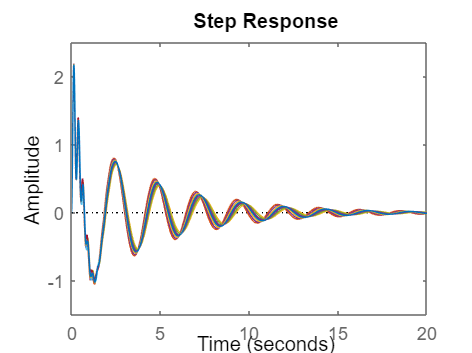


T(1) = feedback(D*G,1);
i=2;
for k = 1:7
    par=[l m_R J_R B_R m_H J_H B_H];
    par(k) = par(k) * 1.05;
    G = (-s/(par(3)-par(5)*par(1)^2))/(s^3 + (par(7)/par(6) + (par(4)+par(7))/(par(3)-par(5)*par(1)^2))*s^2 + ((par(4)*par(7) -(par(2)+par(5))*par(1)*g*par(6))/(par(6)*(par(3)-par(5)*par(1)^2)))*s - ((par(2)+par(5))*par(1)*g*par(7))/(par(6)*(par(3)-par(5)*par(1)^2)));
    T(i) = feedback(D*G,1);
    i = i +1;
    par=[l m_R J_R B_R m_H J_H B_H];
    par(k) = par(k) * .95;
    G = (-s/(par(3)-par(5)*par(1)^2))/(s^3 + (par(7)/par(6) + (par(4)+par(7))/(par(3)-par(5)*par(1)^2))*s^2 + ((par(4)*par(7) -(par(2)+par(5))*par(1)*g*par(6))/(par(6)*(par(3)-par(5)*par(1)^2)))*s - ((par(2)+par(5))*par(1)*g*par(7))/(par(6)*(par(3)-par(5)*par(1)^2)));
    T(i) = feedback(D*G,1);
    i = i +1;
end

for j = 1:size(T,2)
    hold on
    step(T(j))
    xlim([0 20])
end
hold off